clear all;
clc;
close all;

bag = ros2bagreader(["test_multiple/"])

bag =   ros2bagreader with properties:

           FilePath: '/home/robotics/matlab/test_multiple/test_multiple_0.db3'
          StartTime: 1.6941e+09
            EndTime: 1.6941e+09
    AvailableTopics: [1×3 table]
        MessageList: [74190×3 table]
        NumMessages: 74190


% bag_force_z = select(bag,"Topic","/force_z");
% bag_position_desired = select(bag,"Topic","/position_desired");
% bag_position_real = select(bag,"Topic","/position_real");
% bag_surface = select(bag,"Topic","/surface");
bag_data = select(bag,"Topic","/data_control");
bag_data2 = select(bag,"Topic","/data_estimation");

bag_ft2 = select(bag,"Topic","/force_torque_sensor_broadcaster/wrench");
bag_ft = select(bag,"Topic","/bus0/ft_sensor0/ft_sensor_readings/wrench");
% bag_time = select(bag,"Topic","/clock");

% mes_force_z = readMessages(bag_force_z);
% mes_position_desired = readMessages(bag_position_desired);
% mes_position_real = readMessages(bag_position_real);
% mes_surface = readMessages(bag_surface);
mes_data = readMessages(bag_data);
mes_data2 = readMessages(bag_data2);
mes_ft = readMessages(bag_ft);
mes_ft2 = readMessages(bag_ft2);
% mes_time = readMessages(bag_time);
n_mess = bag_data.NumMessages;
% n_v = bag_position_desired.NumMessages;
% n_f = bag_position_real.NumMessages;
n_ft = bag_ft.NumMessages;
n_ft2 = bag_ft2.NumMessages;
%st = min([n_u,n_v,n_f])

sim_time = zeros(n_mess,1);
for i = 1:n_mess
    sim_time(i) =  mes_data{i, 1}.data(1);  
end
initial_time = sim_time(1);
sim_time(:) = sim_time(:)-initial_time;
dT = sim_time(2)

dT = 0.0020


force_z = zeros(n_mess,1);
for i = 1:n_mess
    force_z(i) =  mes_data{i, 1}.data(6);  
end

position_desired = zeros(n_mess,1);
for i = 1:n_mess
    position_desired(i) =  mes_data{i, 1}.data(4);
end

position_real = zeros(n_mess,1);
for i = 1:n_mess
    position_real(i) =  mes_data{i, 1}.data(3);  
end

velocity_z = zeros(n_mess,1);
for i = 1:n_mess
    velocity_z(i) =  mes_data{i, 1}.data(5);  
end

n_palp = zeros(n_mess,1);
for i = 1:n_mess
    n_palp(i) =  mes_data{i, 1}.data(7);  
end

max(n_palp)

ans = 29

for i=1:max(n_palp)+1
    surface_high(i) = mes_data{find(n_palp==i-1,1),1}.data(2);
    x_pos(i) = mes_data{find(n_palp==i-1,1),1}.data(8);
    y_pos(i) = mes_data{find(n_palp==i-1,1),1}.data(9);
end
xv = min(x_pos):0.005:max(x_pos)

xv =    -0.1031   -0.0981   -0.0931   -0.0881   -0.0831   -0.0781   -0.0731   -0.0681   -0.0631   -0.0581   -0.0531   -0.0481   -0.0431   -0.0381   -0.0331   -0.0281   -0.0231   -0.0181   -0.0131   -0.0081   -0.0031    0.0019    0.0069    0.0119    0.0169    0.0219    0.0269    0.0319    0.0369    0.0419    0.0469


yv = min(y_pos):0.005:max(y_pos)

yv =    -0.4021   -0.3971   -0.3921   -0.3871   -0.3821   -0.3771   -0.3721   -0.3671   -0.3621   -0.3571   -0.3521   -0.3471   -0.3421   -0.3371   -0.3321   -0.3271   -0.3221   -0.3171   -0.3121   -0.3071   -0.3021   -0.2971   -0.2921   -0.2871


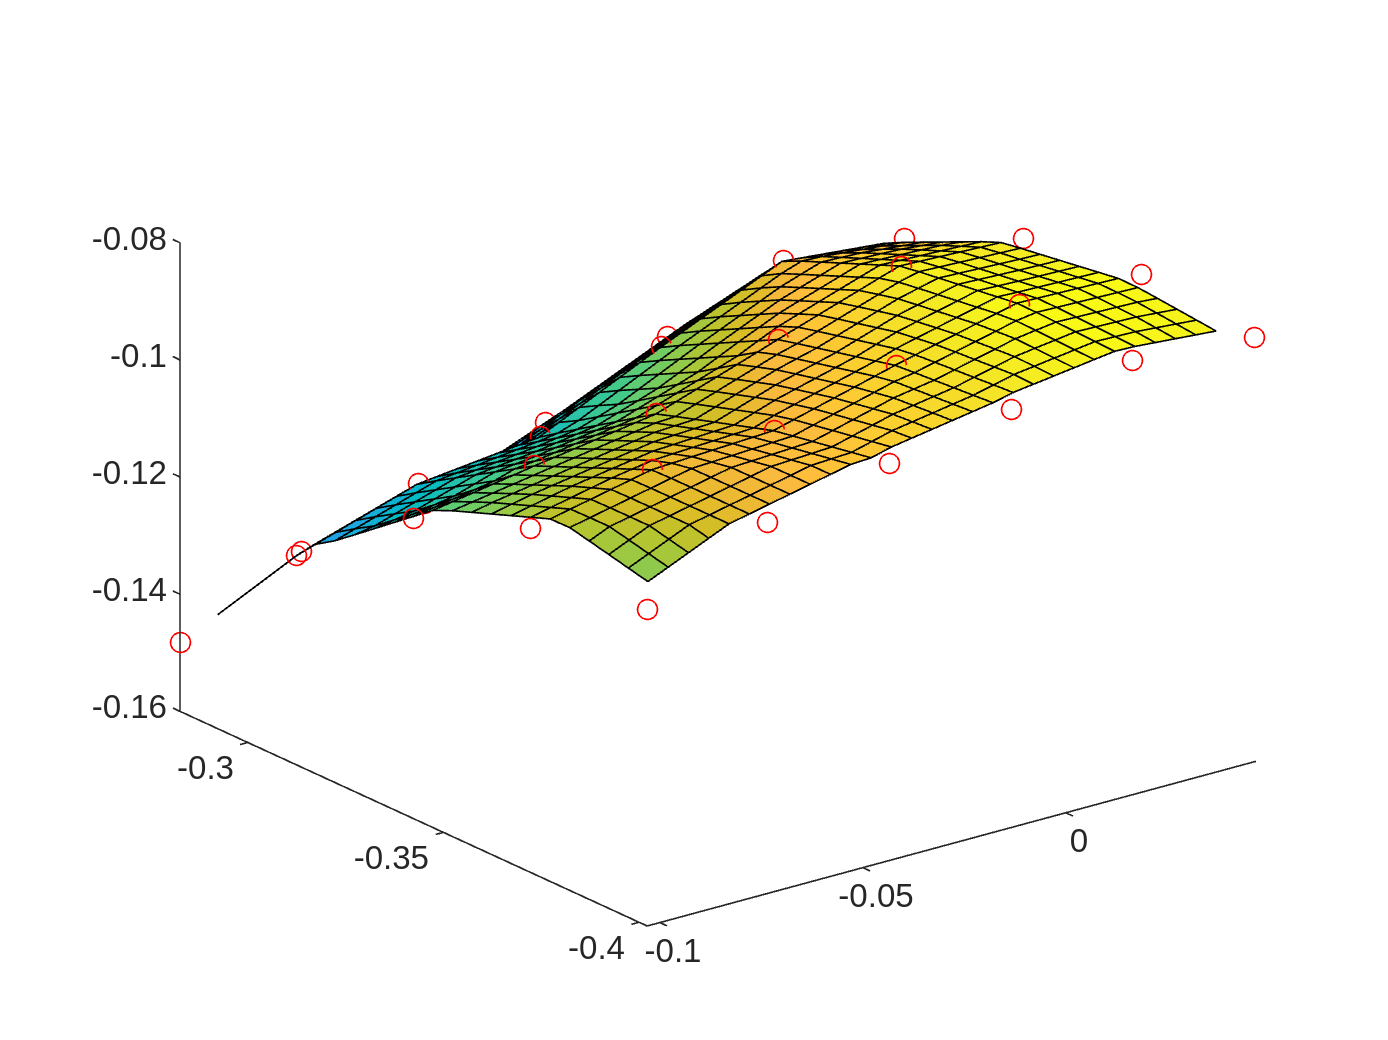

[Xv,Yv] = meshgrid(xv,yv);
Zv = griddata(x_pos,y_pos,surface_high,Xv,Yv);
plot3(x_pos,y_pos,surface_high,"ro")
hold on
surf(Xv,Yv,Zv)
hold off

n =1.35

n = 1.3500

lsqr_method = zeros(3,max(n_palp)+1);
for i=1:max(n_palp)+1
    data_position = find(n_palp==i-1);
    p = 0.0025+surface_high(i) - position_real(data_position);
    pp = velocity_z(data_position);
    ppp = zeros(length(data_position),1);
    ppp(1:length(data_position)-1) = diff(pp)/(dT);
    ppp(length(data_position))=ppp(length(data_position)-1);
    force_z_ext = force_z(data_position);
    lsqr_method(:,i) = real(lsqr([p.^(n),pp.*p.^(n),ppp],force_z_ext));
    
    % plot(lsqr_method(1) * abs(p).^(n) + lsqr_method(2)*pp.* abs(p).^(n) + lsqr_method(3) * ppp)
    % hold on 
    % plot(force_z_ext)
    % hold off 
end

lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.027.
lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.026.
lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.028.
lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.038.
lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.068.
lsqr stopped at iteration 3 without

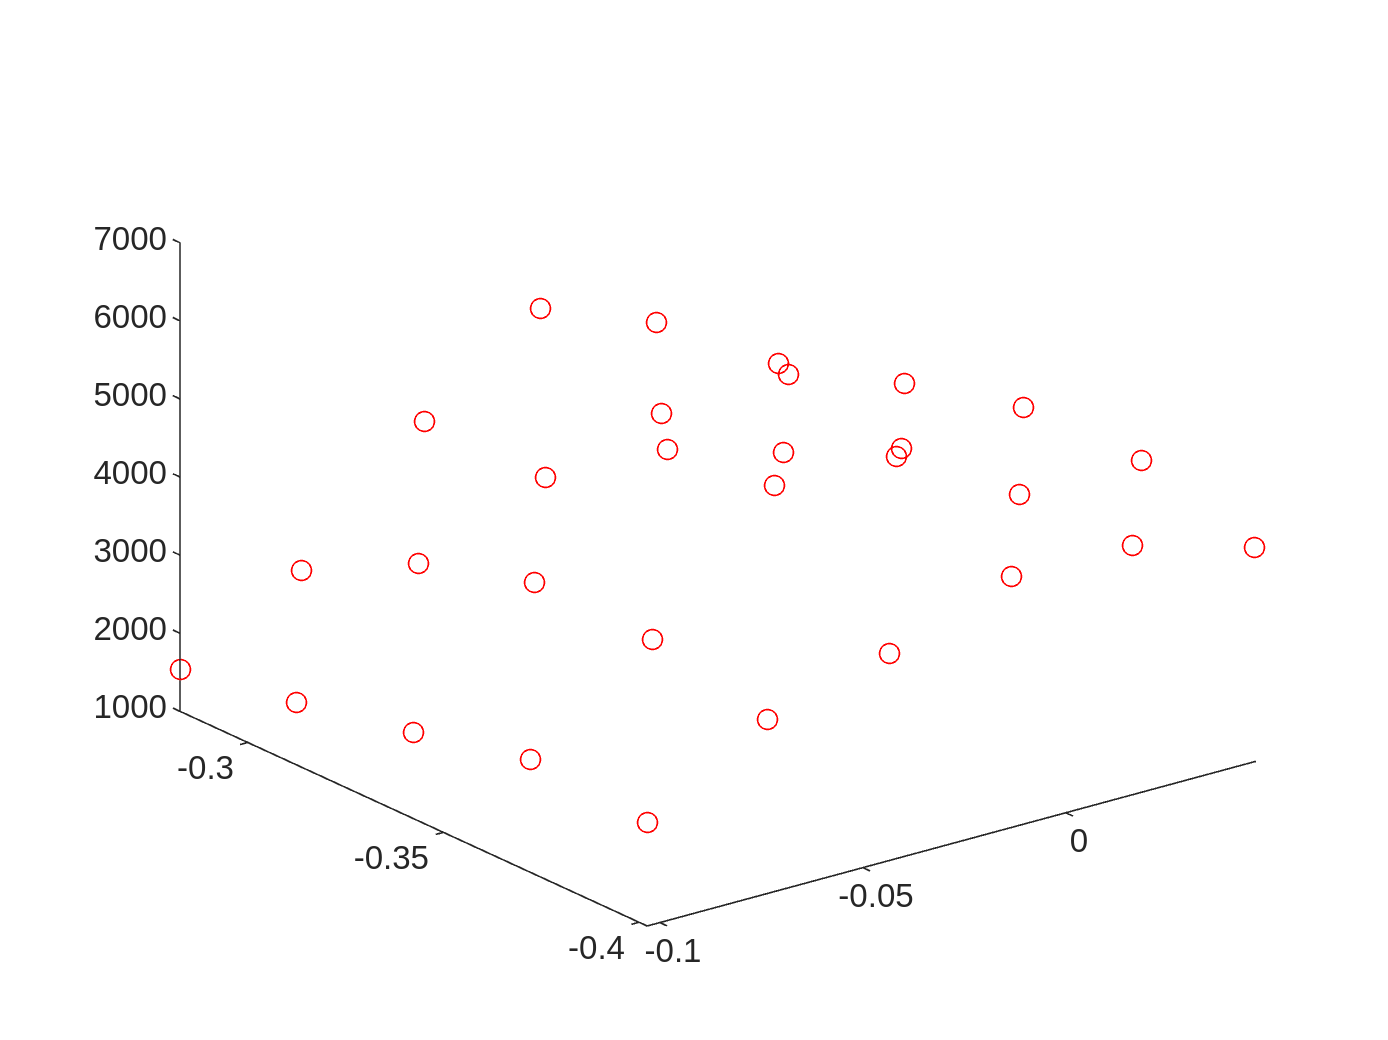

Zk = griddata(x_pos,y_pos,lsqr_method(1,:),Xv,Yv);
plot3(x_pos,y_pos,lsqr_method(1,:),"ro")

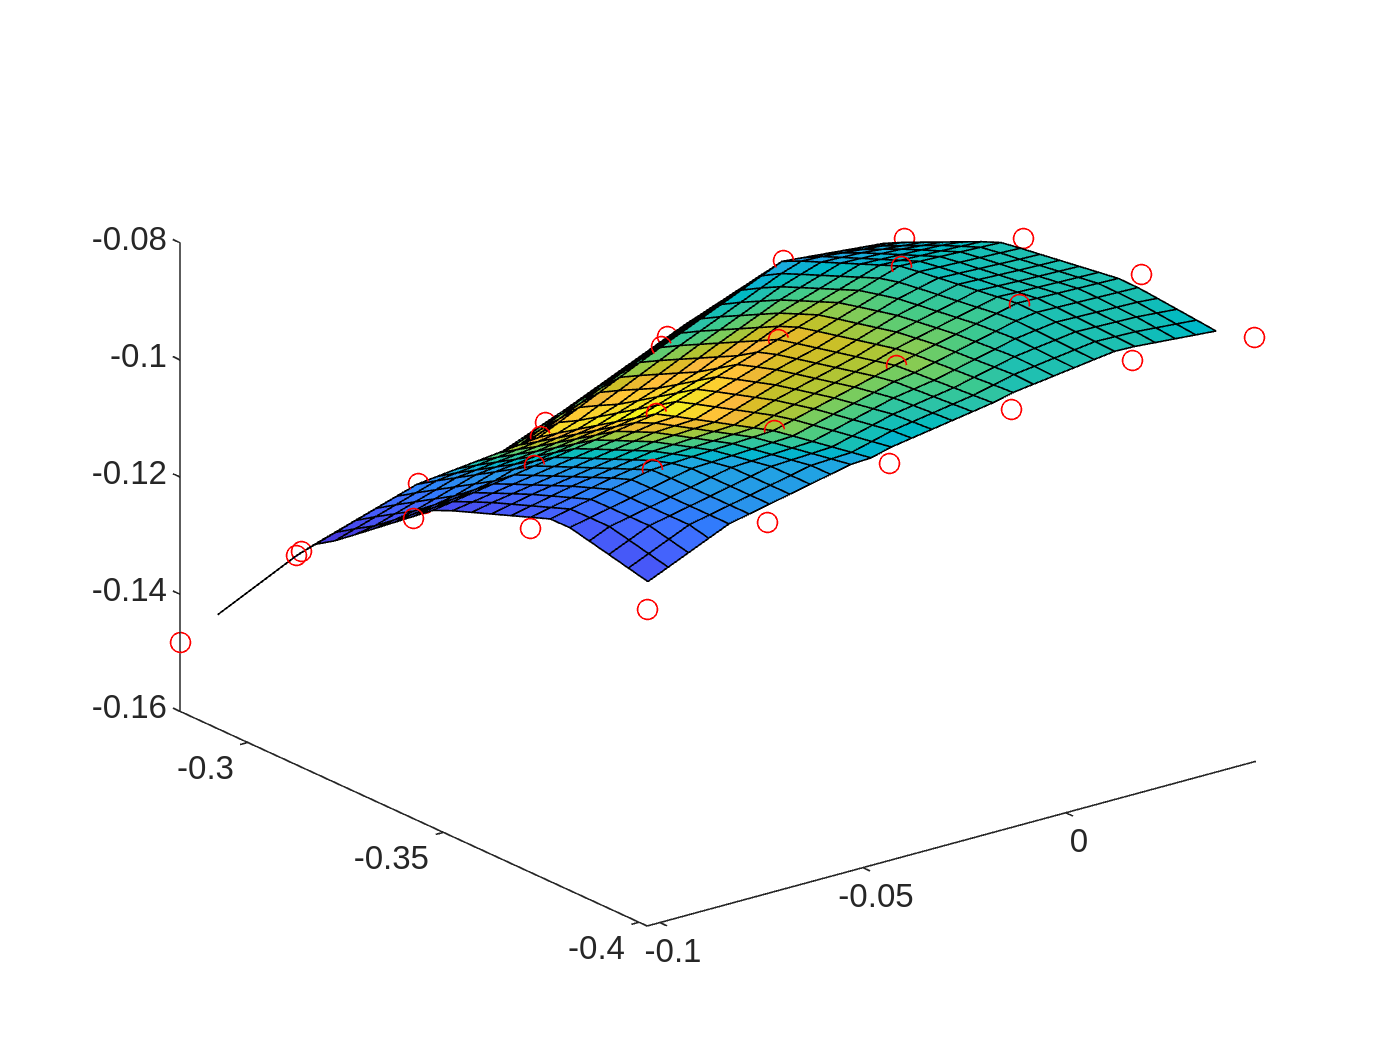

plot3(x_pos,y_pos,surface_high,"ro")
hold on
surf(Xv,Yv,Zv,Zk)
hold off

pos = [x_pos',y_pos'];
gprM = fitrgp(pos,lsqr_method(1,:)',"KernelFunction","squaredexponential");
zPred = predict(gpr,Xv,Yv);

Unrecognized function or variable 'gpr'.


plot3(x_pos,y_pos,surface_high,"ro")
hold on
surf(Xv,Yv,Zv,ZPred)
hold off

%lsqr_method2 = real(lsqr([p(20000:30000),-velocity_z(20000:30000),ppp(20000:30000)],force_z(20037:30037)))

% Get the coefficients 'a' and 'b' from the model
%stiffness = mdl.Coefficients.Estimate(1); % Coefficient for 'x'
%damping = mdl.Coefficients.Estimate(2); % Coefficient for 'y'
%mass = mdl.Coefficients.Estimate(3); % Coefficient for 'y'

%plot(lsqr_method(1) * abs(p).^(1.3) - lsqr_method(2) * velocity_z .*abs(p).^(1.3) + lsqr_method(3) * ppp)
% plot(sim_time,lsqr_method(1) * abs(p).^(1.35) + lsqr_method(2)*pp.* abs(p).^(1.35 ) + lsqr_method(3) * ppp)
% hold on 
% plot(sim_time,force_z)
% hold off 
% %xlim([10000,20000])
% legend(["est","ft_s"])

for i= 1000:1000:30000
    [x,flag,relres,iter,resvec,lsvec] = lsqr([p(1:i).^(n),-velocity_z(1:i).*p(1:i).^(n),ppp(1:i)],force_z(1:i));
    resi(i/1000)=relres;
end
plot(resi)

% tmp = lsqr_method(1) * abs(p).^(1.35) + HC_coeff4(2)*pp.* abs(p).^(1.35) + HC_coeff4(3) * ppp;
% f = force_z(30000:50000) - mean(force_z(30000:50000));
% f2 = tmp(30000:50000) - mean(tmp(30000:50000));
% 
% [~,zero_f] = findpeaks(-abs(f),'MinPeakHeight',-0.03,'MinPeakDistance',100);
% [~,zero_f2] = findpeaks(-abs(f2),'MinPeakHeight',-0.03,'MinPeakDistance',100);
% 
% deltaDelay = mean(sim_time(zero_f) - sim_time(zero_f2))
% deltaSample = mean(zero_f - zero_f2)
% inputData = timeseries(data_in,sim_time);
% save("sim/up.mat","inputData","-v7.3");
% 
% data_in = upp;
% inputData = timeseries(data_in,sim_time);
% save("sim/upp.mat","inputData","-v7.3");
% 
% data_in = -velocity_z;
% inputData = timeseries(data_in,sim_time);
% save("sim/velocity_z.mat","inputData","-v7.3");
% 
% data_in = p;
% inputData = timeseries(data_in,sim_time);
% save("sim/x.mat","inputData","-v7.3");
% 
% data_in = force_z;
% inputData = timeseries(data_in,sim_time);
% save("sim/force.mat","inputData","-v7.3");
% 
% dT = 0.002;
% m0 = lsqr_method(3);